# **Project Two**

## MAT-350: Applied Linear Algebra

## *Sulochana Pradhan*

## *04/12/2023*

# **Problem 1**

**Use the svd() function **in MATLAB to compute $A_{1}$, the **rank-1 approximation of **$A$**. **Clearly state what $A_{1}$ is, rounded to 4 decimal places. Also, **compute** the root-mean square error (RMSE) between $A$ and $A_{1}$.

### Solution:

%code
A = [1 2 3; 3 3 4; 5 6 7];
[U, S, V] = svd(A);
%rank 1
k = 1;
% Performing rank-1 approximation
A1 = U(:, 1:k) * S(1:k, 1:k) * V(:, 1:k).'

A1 =     1.7039    2.0313    2.4935
    2.7243    3.2477    3.9867
    4.9087    5.8517    7.1832


% Get size of matrix
[m, n] = size(A)

m = 3

n = 3

% Calculate root mean square error
RMSE1 = norm(A-A1, 'fro')/sqrt(m*n)

RMSE1 = 0.3257

# **Problem 2**

**Use the svd() function** in MATLAB to compute $A_{2}$, the** rank-2 approximation of **$A$. Clearly state what $A_{2}$ is, rounded to 4 decimal places. Also, **compute** the root-mean square error (RMSE) between $A$ and $A_{2}$. Which approximation is better, $A_{1}$ or $A_{2}$? Explain.

### Solution:

%code
% rank-2 approximation
k = 2;
A2 = U(:, 1:k) * S(1:k, 1:k) * V(:, 1:k).';
% Calculate root mean square error
RMSE2 = norm(A-A2, 'fro')/sqrt(m*n)

RMSE2 = 0.1166

**Explain: **Clearly, we can see that RMSE2 is smaller than RMSE1. So, rank-2 approximation is better than rank-1 approximation. This makes sense as A2 holds more information than A1. 

# **Problem 3**

For the $3 \times 3$ matrix $A$, the singular value decomposition is $A=USV'$ where $U=[\mathbf{u}_{1} \text{ } \mathbf{u}_{2} \text{ } \mathbf{u}_{3}]$. Use MATLAB to **compute **the dot product $d_{1}=dot(\mathbf{u}_{1},\mathbf{u}_{2})$.  

Also, use MATLAB to **compute **the cross product $\mathbf{c} =cross(\mathbf{u}_{1},\mathbf{u}_{2})$ and dot product $d_{2} = dot(\mathbf{c},\mathbf{u}_{3})$. Clearly state the values for each of these computations. Do these values make sense? **Explain**.

### Solution:

%code
u1 = U(:, 1:1);
u2 = U(:, 2:2);
u3 = U(:, 3:3);
d1 = dot(u1, u2)

d1 = 1.6653e-16

c = cross(u1, u2)

c =    -0.1114
   -0.8520
    0.5115


d2 = dot(c, u3)

d2 = 1.0000

**Explain: **U is a 3x3 orthogonal matrix. As u1 and u2 are orthogonal, the inner product should be 0. We can see d1 can be rounded to 0. The c is just the cross product of u1 and u2 and is orthogonal to both u1 and u2. As c is exactly the same as u3. As a result, d2 equals to 1 implies parallel vectors.  

# **Problem 4**

Using the matrix $U=[\mathbf{u}_{1} \text{ } \mathbf{u}_{2} \text{ } \mathbf{u}_{3}]$, d**etermine whether or not the columns of **$U$ **span **$\mathbb{R}^{3}$. **Explain your approach.**

### Solution:

%code
% Create augumented matrix using u1, u2, and u3
U = [u1 u2 u3];
% Reduce the matrix
[rowreducedU, pivotvarsA] = rref(U)

rowreducedU =      1     0     0
     0     1     0
     0     0     1


pivotvarsA =      1     2     3


% check rank of rowreducedU
[numRows, numPivotvars] = size(pivotvarsA)

numRows = 1

numPivotvars = 3

**Explain:** The rowreducedU matrix has 3 pivot columns and no zero rows. So the columns of U span $\mathbb{R}^{3}$. We can see the numPivotvars is 3. 

# **Problem 5**

Use the MATLAB imshow() function to load and display the image $A$ stored in the image.mat file, available in the Project Two Supported Materials area in Brightspace. For the loaded image, **derive the value of **$k$ that will result in a compression ratio of $CR \approx 2$. For this value of $k$, **construct the rank-*****k***** approximation of the image**. 

### Solution:

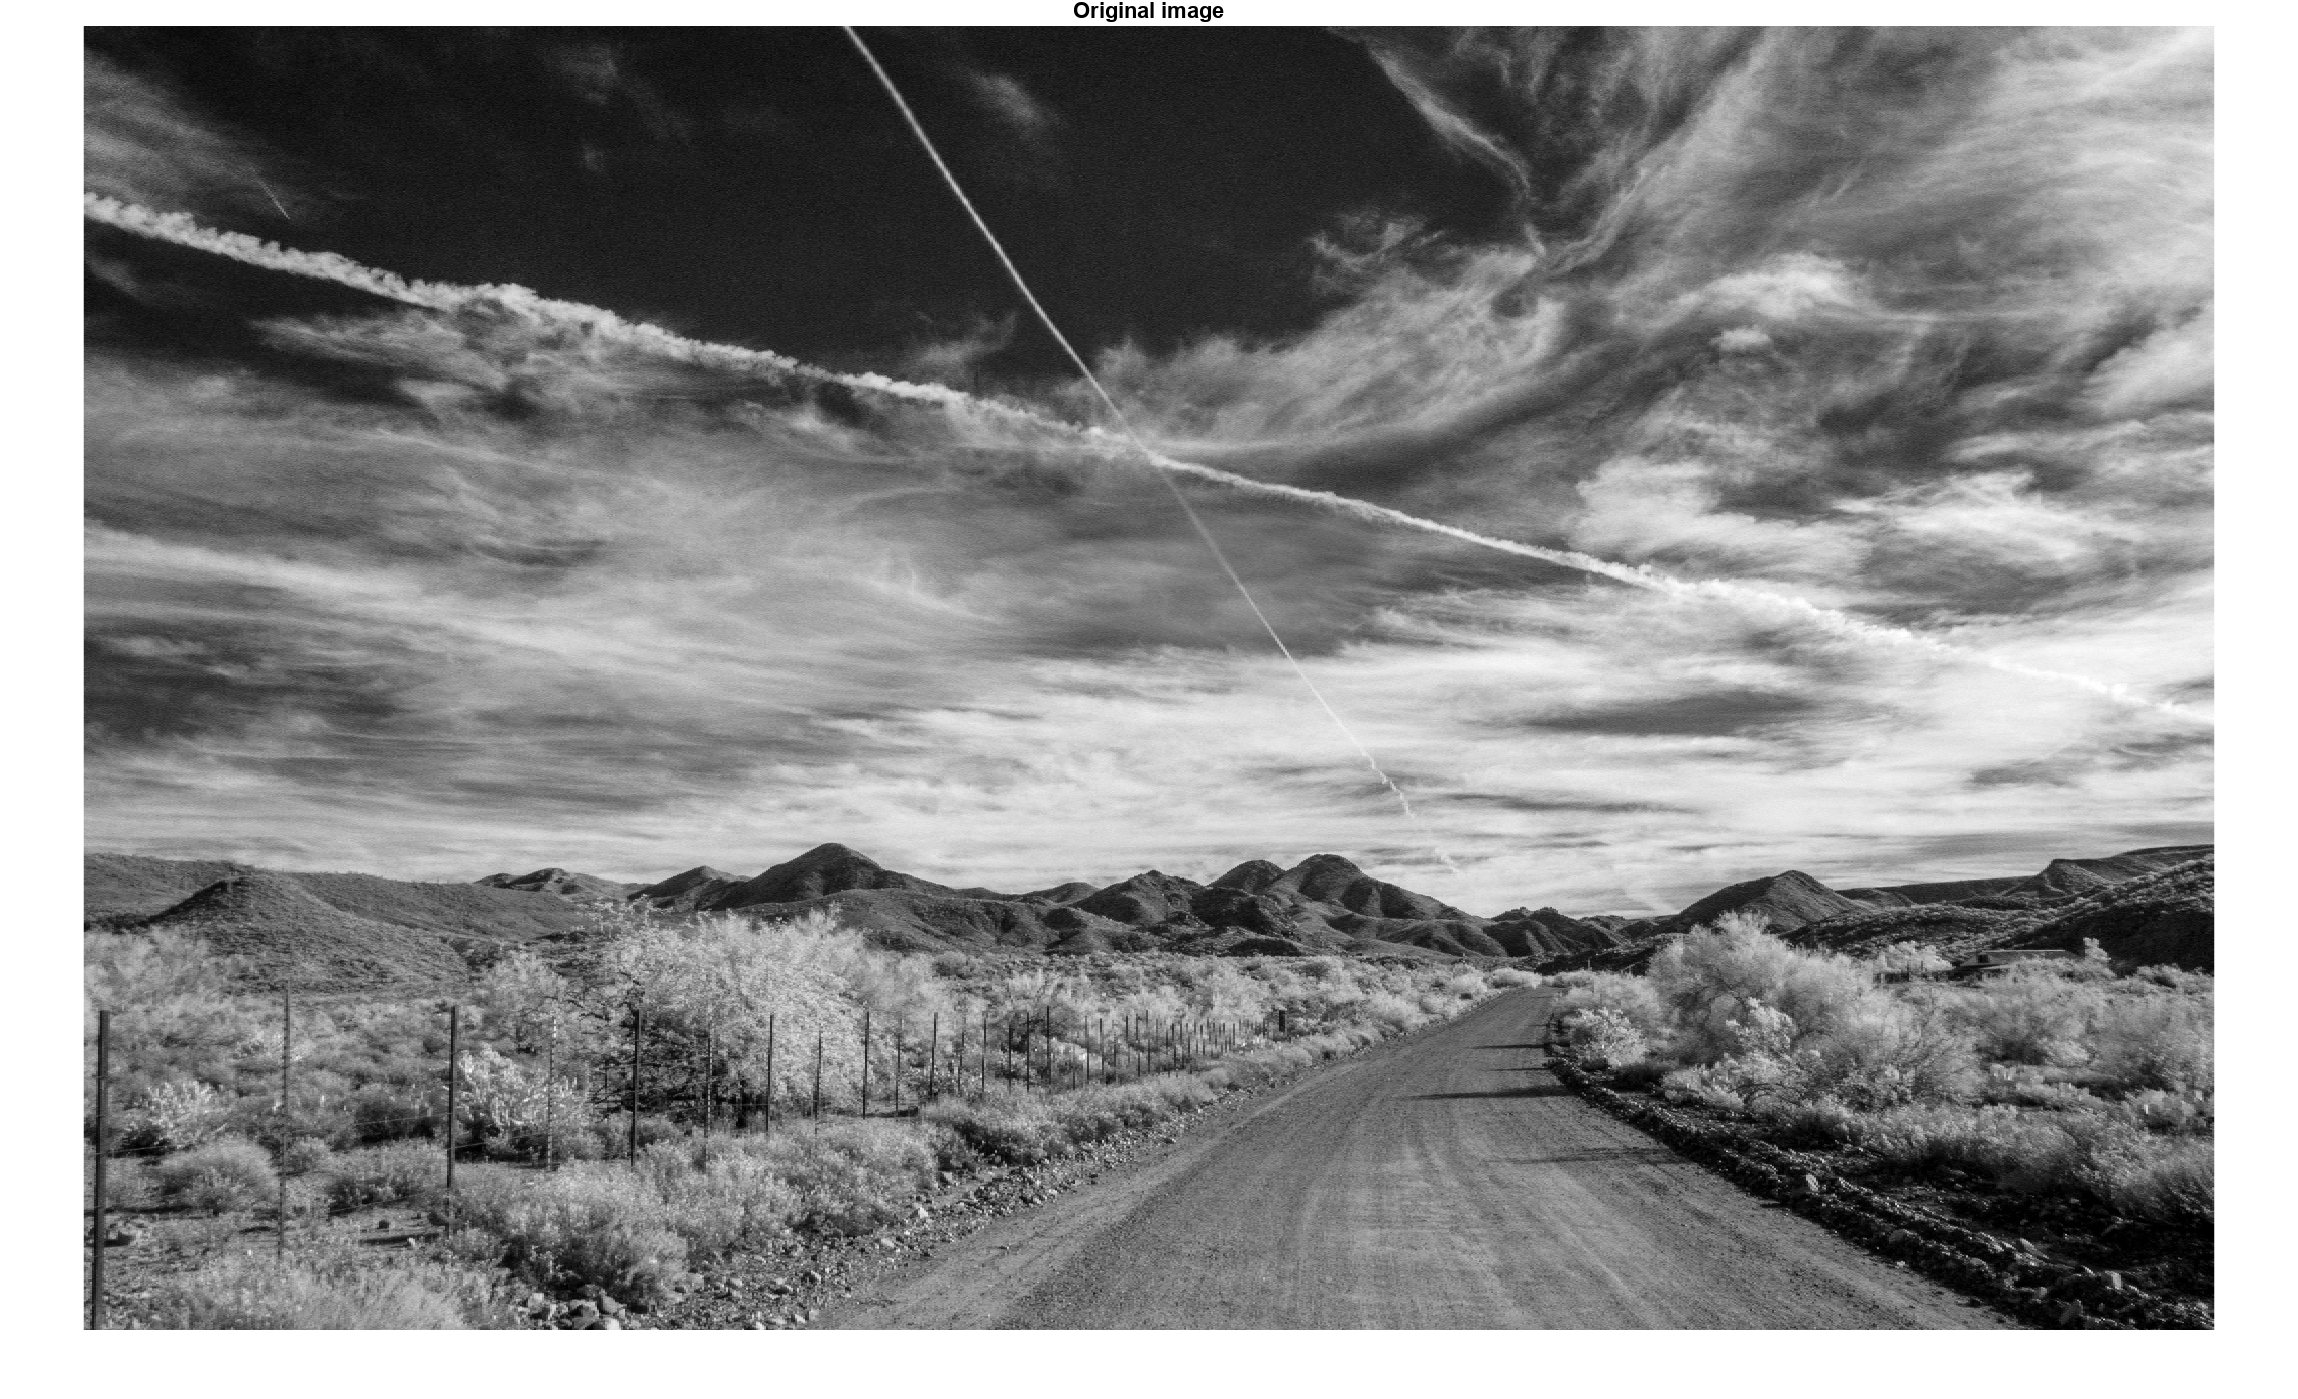

%code
%Load image Image.mat
load Image.mat
% Display image
imshow(A)
title('Original image')

% SVD to U, S, V
[U S V] = svd(double(A));
% Find matrix dimension
[m, n] = size(S);
% For CR2 = 2, determine k
CR2 = 2;
k2 = round((m*n)/(CR2 * (m + n + 1)))

k2 = 801


ACR2 = U(:, 1:k2) * S(1:k2, 1:k2) * V(:, 1:k2).';
% Make sure the rank is same as 801-rank approximation
rank(ACR2)
% integer conversion to display image
ACR2 = uint8(round(ACR2));

**Explain:  **The loaded image has a matrix dimension of 2538 X 4220. Using the formula k = mn/(CR(m+n+1)), k is calculated for CR = 2 which is 801. Then, the rank-801 approximation is done. Finally, values are rounded to an integer to display the image. 

# **Problem 6**

**Display the image and compute** the root mean square error (RMSE) between the approximation and the original image. Make sure to include a copy of the approximate image in your report.

### Solution:

%code
imshow(ACR2)
title(strcat('Image when CR = ', num2str(CR2), ' and K = ', num2str(k2)))
% Cacluate RMSE
RMSECR2 = norm(double(A)-double(ACR2), 'fro')/sqrt(m*n)

# **Problem 7**

**Repeat** Problems 5 and 6 for $CR \approx 10$, $CR \approx 25$, and $CR \approx 75$. **Explain** what trends you observe in the image approximation as $CR$ increases and provide your recommendation for the best $CR$ based on your observations. Make sure to include a copy of the approximate images in your report.

### Solution:

%code I have created a function perform_rank_approximation to calculate the k and perform
%approximation at the bottom. 
% Peform approximation for CR = 25
rmse10 = perform_rank_approximation(A, U, S, V, 10, m, n)
% Peform approximation for CR = 25
rmse25 = perform_rank_approximation(A, U, S, V, 25, m, n)
% Peform approximation for CR = 25
rmse75 = perform_rank_approximation(A, U, S, V, 75, m, n)

% Function to calculate k based on the given CR, perform approximation,
% plot image, and calculate RMSE

function rmse = perform_rank_approximation(A, U, S, V, CR, m, n)
    % Determine the k based on CR
    k = round((m*n)/(CR * (m + n + 1)));
    disp(strcat('k = ', num2str(k)))
    % Perform k-rank approximation
    Acr =  U(:, 1:k) * S(1:k, 1:k) * V(:, 1:k).';
    % Make sure the rank is same 
    disp(strcat('Rank = ', num2str(rank(Acr))))
    Acr = uint8(round(Acr));
    % Display image
    imshow(Acr)
    title(strcat('Image when CR = ', num2str(CR), ' and K = ', num2str(k)))
    % Cacluate RMSE
    rmse = norm(double(A)-double(Acr), 'fro')/sqrt(m*n);
end

**Explain: **I have created a function to determine the k based on the CR, perform approximation, display the image, and calculate the RMSE. This function is called for different CR: 10, 25, and 75. Clearly, when the CR is increased there is an increase in RMSE. This makes sense because the higher the CR lower the value of k. This means a lot of information is lost when CR is higher. We can see the decreased quality of the image for the higher CR value. For me there is no significant difference between the original image and the image when CR=10, however, we can clearly see the reduced quality when CR = 25, and 75. 